Nbits = 1e6;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

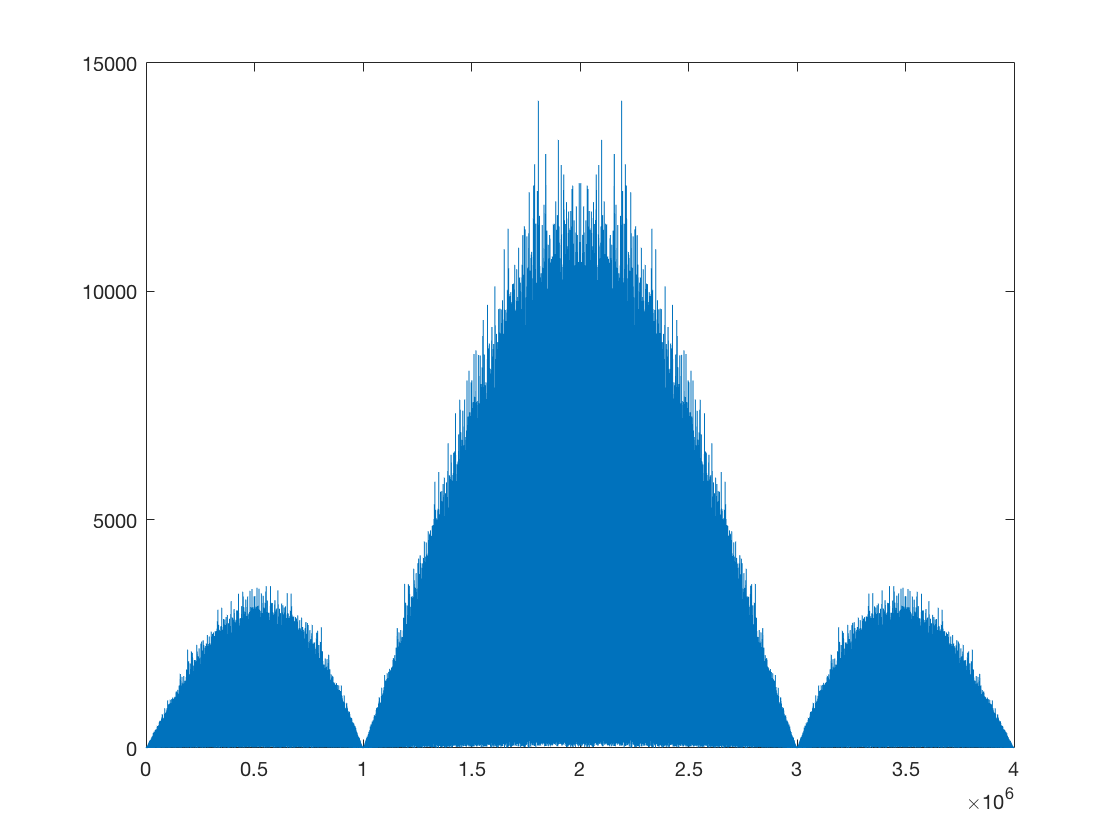

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);
%Tc=1/R_s/SpS;
d_f = 1/Nbits;
f = (-(SpS/2):d_f:(SpS/2-d_f))';
f_p = 1.5;

% NRZ
for a=0:Nbits-1
    for b=1:SpS
        v_t(a*SpS+b) = in(a+1);
    end
end

figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t))))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);

for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    H_rx = 1./(1+1i*(f/f_p));
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Vediamo su quale bit è meglio campionare

    BERs = zeros(SpS, 1);
    for bit = 1:SpS
        r = y(bit:SpS:end) > 0;
        r = 2*r-1;
        err = in ~= r;
        BERs(bit) = sum(err)/Nbits;
    end
    BERs
    [m, i] = min(BERs);
    i

Scegliamo di campionare sul bit i-esimo (è sempre il primo)

    r = y(i:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

BERs =     0.2087
    0.3180
    0.3675
    0.4376


i = 1

BERs =     0.1924
    0.2997
    0.3543
    0.4302


i = 1

BERs =     0.1771
    0.2813
    0.3398
    0.4238


i = 1

BERs =     0.1629
    0.2606
    0.3239
    0.4165


i = 1

BERs =     0.1494
    0.2422
    0.3074
    0.4098


i = 1

BERs =     0.1378
    0.2212
    0.2923
    0.4020


i = 1

BERs =     0.1266
    0.2027
    0.2751
    0.3948


i = 1

BERs =     0.1158
    0.1842
    0.2590
    0.3873


i = 1

BERs =     0.1053
    0.1661
    0.2444
    0.3805


i = 1

BERs =     0.0956
    0.1506
    0.2297
    0.3754


i = 1

BERs =     0.0863
    0.1365
    0.2162
    0.3706


i = 1

Plotting

err_arr

err_arr =     0.2087
    0.1924
    0.1771
    0.1629
    0.1494
    0.1378
    0.1266
    0.1158
    0.1053
    0.0956


figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

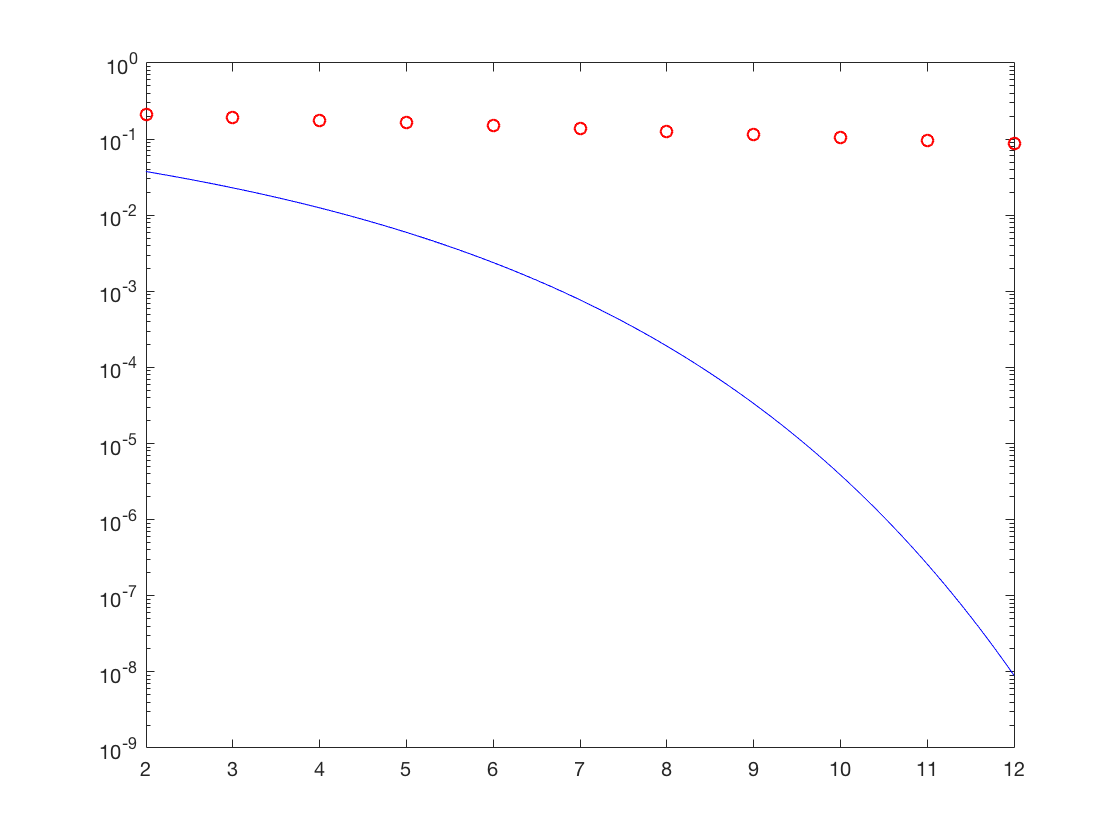

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')

Diagramma ad occhio

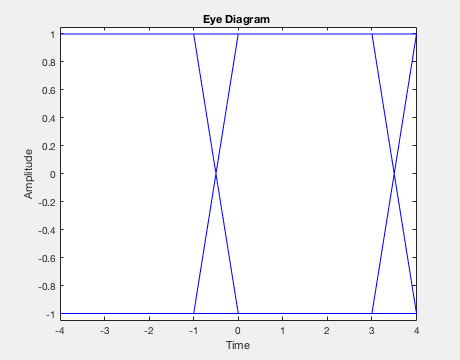

figure(3)
eyediagram(v_t(1:2000*SpS), 2*SpS, 2*SpS);

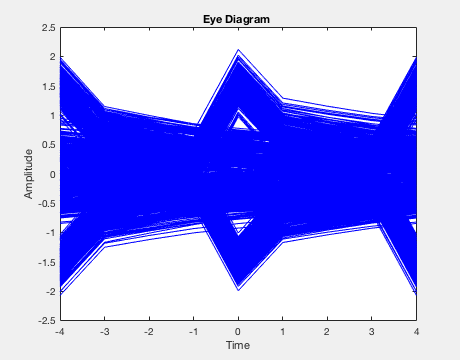



X_f_nn = fft(v_t);
Y_f_nn = H_rx .* X_f_nn;
y_nn = real(ifft(Y_f_nn));
figure(4)
eyediagram(y_nn(1:2000*SpS), 2*SpS, 2*SpS);